# SSY191 - Assignment 01

#### Lucas Rath

## Problem 1

% Rotation matrices (can be used with symbolic variables)
rotz = @(th) [cos(th) -sin(th) 0; sin(th) cos(th) 0; 0 0 1];
rotx = @(th) [1 0 0; 0 cos(th) -sin(th); 0 sin(th) cos(th)];
roty = @(th) [cos(th) 0 sin(th); 0 1 0; -sin(th) 0 cos(th)];

% The rotation YXZ is given by:
syms phi theta psi
Ryxz = roty(theta) * rotx(phi) * rotz(psi)

$$Ryxz = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right) & -\sin\left(\varphi \right)\\ \cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\theta \right) & \sin\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

syms fx fy fz

[fx fy fz].' == Ryxz * [0 0 1].'

$$ans = \left(\begin{array}{c} \mathrm{fx}=\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \mathrm{fy}=-\sin\left(\varphi \right)\\ \mathrm{fz}=\cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

By analyzing the set of equations above, we then observe that the angles $\phi$ and $\theta$ can be calculated by first dividing the first by the last equation:


$$\begin{array}{l}
\mathrm{tan}\left(\theta \right)=\frac{\mathrm{fx}}{\mathrm{fz}}\;\;\\
\Rightarrow \;\;\theta =\mathbf{atan2}\left(\mathbf{fx},\mathbf{fz}\right)
\end{array}$$


In addition, we have:


$$\begin{array}{l}
\sqrt{\left({\mathrm{fx}}^2 +{\mathrm{fz}}^2 \right)}=\mathrm{cos}\left(\phi \right)\\
\mathrm{fy}=-\mathrm{sin}\left(\phi \right)\\
\Rightarrow \phi =\mathbf{atan2}\left(-\mathbf{fy},\sqrt{\left(\mathbf{fx}+{\mathbf{fz}}^2 \right)}\right)
\end{array}$$


As a last improvement, one can also normalize the readings from the accelerometer each time step, and then use the same two formulas described above to get the Euler angles. This will enhance the performance of our estimator when the body is accelerating ($a^I \not= 0$), which is ideally not desired.

## Problem 2

Using the two given equations, we get that the fused and filtered signal $\theta \left(s\right)$ can be written as:


$$\theta \;\left(s\right)=G\left(s\right)\;\theta_a \left(s\right)+\left(1-G\left(s\right)\right)\;\frac{1}{s}y_g$$


where $G\left(s\right)$is the low pass filter, such that we want to low-pass the angle from the accelerometer and high-pass $\left(1-G\left(s\right)\right)$ the integrated signal from the gyro:

$G\left(s\right)=\frac{1}{\alpha \;s+1}$,   where $\frac{1}{\alpha }$ is the cutoff frequency

Puting everything together we get:


$$\begin{array}{l}
\theta \;\left(s\right)=\frac{1}{\alpha \;s+1}\;\theta_a \left(s\right)+\left(1-\frac{1}{\alpha \;s+1}\right)\;\frac{1}{s}y_g \\
\Rightarrow \;\;\left(\alpha \;s+1\right)\;\theta =\theta_a +\alpha \;y_g \\
\Rightarrow \;\;\;\;\;\;\alpha \;s\;\theta +\theta =\theta_a +\alpha \;y_g 
\end{array}$$


We can now discretize the system using Euler backward discretization:

$\dot{x} \left(t\right)=s\ldotp x\left(s\right)\approx \frac{x_k -x_{k-1} }{h}$,     where h is the sampling period

It then follows that:


$$\alpha \;\frac{\left(\theta_k -\theta_{k-1} \right)}{h}+\theta_k =\theta_{a,k} +\alpha \;y_{g,k}$$



$$\Rightarrow \frac{\left(\alpha +h\right)}{h}\theta_k =\frac{\alpha }{h}\theta_{k-1} +\theta_{a,k} +\alpha \;y_{g,k}$$



$$\Rightarrow \theta_k =\frac{h}{h+\alpha }\;\theta_{a,k} +\frac{\alpha }{h+\alpha }\left(\theta_{k-1} +h\ldotp y_{g,k} \right)$$


Finally, by calling $\gamma =\frac{\alpha }{h+\alpha }$, we get the final expression:


$$\theta_k =\left(1-\gamma \right)\;\theta_{a,k} +\gamma \;\left(\theta_{k-1} +h\ldotp y_{g,k} \right)$$
 

where the subindex k means the signal time step, $\theta_k =\theta \left(h\ldotp k\right)$.

## Problem 3

**A)** If follows below in Figure 1, the automata of the water control system:

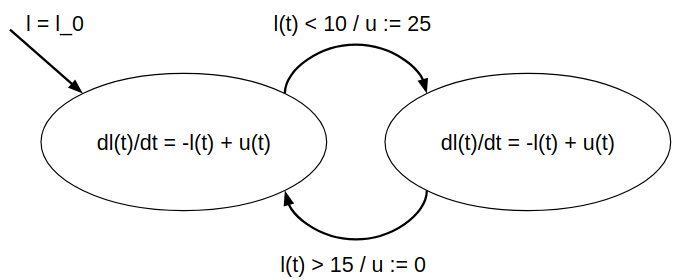

**Figure 1**: Automata of the water control system problem

**B)** We can then proceed to implement this automata in Simulink, as can be seen in Figure 2. Here it was made use of a SR flip-flop, which will allow the detection of the transitions between states and consequently set the right input.

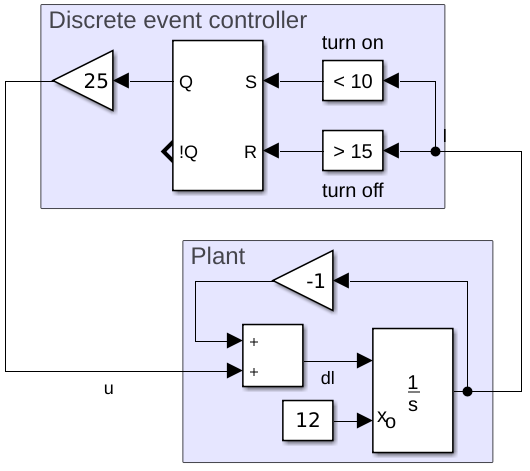

**Figure 2**: Block diagram of the water control system

The Simulink model was then simulated for two scenarios, with and without zero-crossing detection. The results can be seen below in Figure 3:

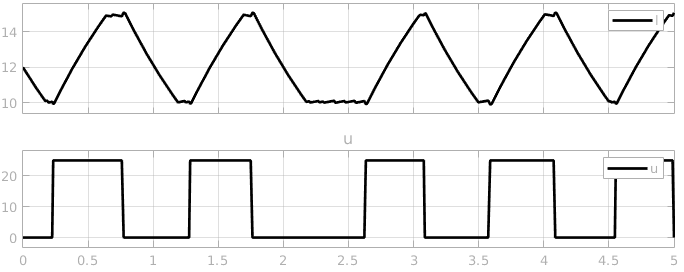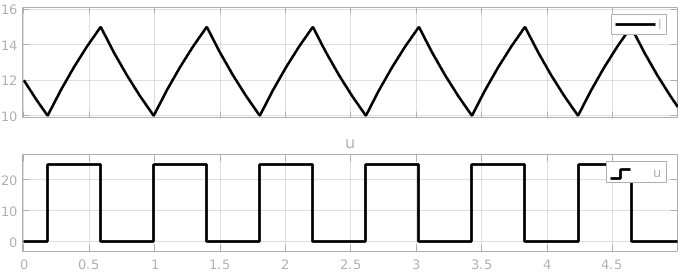

**Figure 3**: Simulation of the water control system without (on the left) and with (on the right) zero-crossing detection

**C)** The hybrid automaton is not ZENO, because it is not possible to have infinite transitions in a finite amount of time. We can conclude this because the system is continuous and there is a transition region (10 < l < 15), necessary to switch the sate. That means that whenever the pump is turned on or off, the water level will have to increase or decrease 5m to be able to change the state again.

**D)** The hybrid automata is always safe because according to the differential equations, the water level will decrease imediately when the input is 0 (off) and it will increase imediately when the input is 25 (on). Moreover, the discrete controller will be always turned off if the water level is greater than 15 and turned on when the level is below 10. We then conclude that if we have a initial condition that is already in safe interval [0,20], the water tank will always remain in safe confition. To illustrate this behaviour, the system was simulated for the extrem condition, when the initial level is 20, see Figure 4. As expeceted, the water level never goes above 20 and below 10.

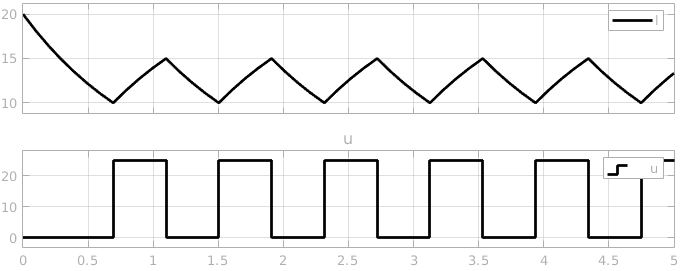

**Figure 4**: Simulation of the water control system for initial condition l_0=20